for i = 594
    tiff_name = ['20221203AchsensorHEK003', num2str(i), '.tif']
    t = Tiff(tiff_name, 'r');
    imageData = imread(tiff_name)
    imageData = read(t)
    imageData = double(imageData)-background;
%     eval(['imageData_', num2str(i), '=imageData;']);
end

tiff_name = '20221203AchsensorHEK003594.tif'

imageData = 128×128 uint16 matrix
   34   29   32   32   33   33   32   33   34   32   31   32   33   31   33   31   31   31   33   31   31   33   33   33   32   33   31   32   32   34   33   32   30   29   33   31   34   34   32   33   35   35   37   37   35   33   31   31   33   31
   31   30   31   31   33   30   33   32   30   32   32   33   33   32   32   31   31   32   31   32   32   32   31   33   31   31   31   31   33   31   29   33   34   32   32   32   32   32   31   33   31   31   33   32   33   33   31   34   33   34
   33   30   32   33   34   32   33   30   32   32   32   31   32   32   34   32   31   31   32   31   33   32   32   33   33   32   33   31   33   32   33   32   32   32   29   33   32   32   34   32   33   32   33   32   32   31   32   32   33   33
   32   33   36   32   33   31   32   32   32   33   31   34   32   34   29   32   32   33   33   31   33   33   32   32   34   31   30   31   33   31   32   34   31   31   32   31   31   30   34   33   32   32   

imageData = 128×128 uint16 matrix
   34   29   32   32   33   33   32   33   34   32   31   32   33   31   33   31   31   31   33   31   31   33   33   33   32   33   31   32   32   34   33   32   30   29   33   31   34   34   32   33   35   35   37   37   35   33   31   31   33   31
   31   30   31   31   33   30   33   32   30   32   32   33   33   32   32   31   31   32   31   32   32   32   31   33   31   31   31   31   33   31   29   33   34   32   32   32   32   32   31   33   31   31   33   32   33   33   31   34   33   34
   33   30   32   33   34   32   33   30   32   32   32   31   32   32   34   32   31   31   32   31   33   32   32   33   33   32   33   31   33   32   33   32   32   32   29   33   32   32   34   32   33   32   33   32   32   31   32   32   33   33
   32   33   36   32   33   31   32   32   32   33   31   34   32   34   29   32   32   33   33   31   33   33   32   32   34   31   30   31   33   31   32   34   31   31   32   31   31   30   34   33   32   32   


info = imfinfo(tiff_name)

info = 3×1 struct array with fields:
    Filename
    FileModDate
    FileSize
    Format
    FormatVersion
    Width
    Height
    BitDepth
    ColorType
    FormatSignature
    ByteOrder
    NewSubFileType
    BitsPerSample
    Compression
    PhotometricInterpretation
    StripOffsets
    SamplesPerPixel
    RowsPerStrip
    StripByteCounts
    XResolution
    YResolution
    ResolutionUnit
    Colormap
    PlanarConfiguration
    TileWidth
    TileLength
    TileOffsets
    TileByteCounts
    Orientation
    FillOrder
    GrayResponseUnit
    MaxSampleValue
    MinSampleValue
    Thresholding
    Offset
    ImageDescription


offsets = getTag(t)

Not enough input arguments.

Error in Tiff/getTag (line 848)
            switch(class(tagId))

dirNum = 1; 
setDirectory(t,dirNum);
setSubDirectory(t,offsets(1));
subimage_one = read(t)

max(max(imageData))

ans = uint16
73

imageData = double(imageData)

imageData =     34    29    32    32    33    33    32    33    34    32    31    32    33    31    33    31    31    31    33    31    31    33    33    33    32    33    31    32    32    34    33    32    30    29    33    31    34    34    32    33    35    35    37    37    35    33    31    31    33    31
    31    30    31    31    33    30    33    32    30    32    32    33    33    32    32    31    31    32    31    32    32    32    31    33    31    31    31    31    33    31    29    33    34    32    32    32    32    32    31    33    31    31    33    32    33    33    31    34    33    34
    33    30    32    33    34    32    33    30    32    32    32    31    32    32    34    32    31    31    32    31    33    32    32    33    33    32    33    31    33    32    33    32    32    32    29    33    32    32    34    32    33    32    33    32    32    31    32    32    33    33
    32    33    36    32    33    31    32    32    32    33    31    34    32    34 

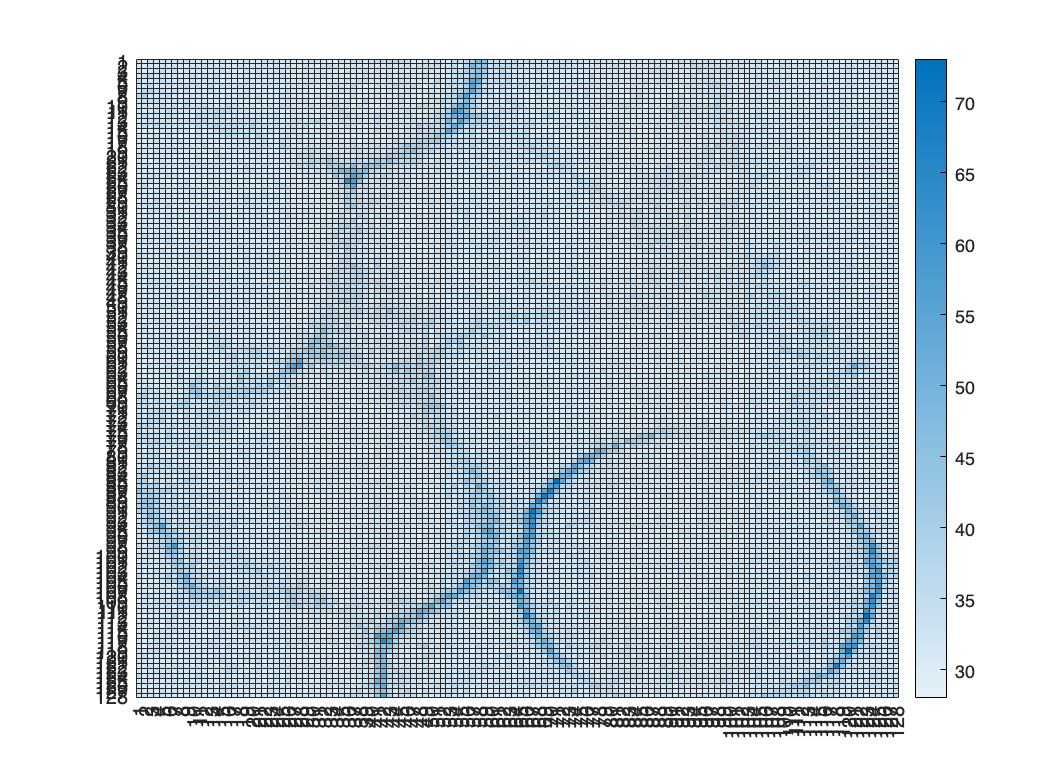

figure
heatmap(imageData)

spc_name = ['20221203AchsensorHEK003','FLIM',num2str(i),'.mat']


tiff_stack1 = imread(tiff_name, 1)

tiff_stack1 = 128×128 uint16 matrix
   34   29   32   32   33   33   32   33   34   32   31   32   33   31   33   31   31   31   33   31   31   33   33   33   32   33   31   32   32   34   33   32   30   29   33   31   34   34   32   33   35   35   37   37   35   33   31   31   33   31
   31   30   31   31   33   30   33   32   30   32   32   33   33   32   32   31   31   32   31   32   32   32   31   33   31   31   31   31   33   31   29   33   34   32   32   32   32   32   31   33   31   31   33   32   33   33   31   34   33   34
   33   30   32   33   34   32   33   30   32   32   32   31   32   32   34   32   31   31   32   31   33   32   32   33   33   32   33   31   33   32   33   32   32   32   29   33   32   32   34   32   33   32   33   32   32   31   32   32   33   33
   32   33   36   32   33   31   32   32   32   33   31   34   32   34   29   32   32   33   33   31   33   33   32   32   34   31   30   31   33   31   32   34   31   31   32   31   31   30   34   33   32   32 

tiff_stack2 = imread(tiff_name, 2)

tiff_stack2 = 128×128 uint16 matrix
    656    717    897    966   1094   1203   1189   1053   1041    923    730    750    690    819   1041    900    704    939   1223   1136   1167   1162   1279   1077    987   1041   1060   1217   1094   1072   1067   1073    994   1003    977   1024   1058   1071    968    734    601    556   1133   1754   1536   1468   1454   1471   1119    946
    791    684    732    929   1006   1189   1160   1085    853    803    749    731    813    978    953    969   1121   1195   1062   1138    945   1042   1143   1185   1184   1033   1237   1080   1127    903    863    992   1018   1106   1103   1178   1261   1204   1052    855    816    992   1445   1937   1525   1180   1166   1175    830    666
    608    591    485    407    731    887    929    989    965    934   1026   1064   1133   1189    912    985   1043   1114   1177    943    996   1051   1223   1022   1108   1042   1022   1052   1167    972   1089    969   1172   1120   1002   1124   1043   

tiff_stack3 = imread(tiff_name, 3)

tiff_stack3 = 128×128 uint16 matrix
   10    1    4    1    2    2    2    0    1    2    1    1    3    0    2    0    3    0    0    1    1    5    0    3    3    2    1    2    1    1    3    1    3    1    0    1    2    1    2    4    8   16   21   27   25   26   11   10   15    4
    2    6    4    1    1    0    2    1    1    1    1    3    0    2    2    0    5    1    1    1    0    0    1    0    0    1    4    2    1    0    2    2    3    2    2    2    1    3    3    8   19   10   13   12   17   12   11    5    9    6
    7    5   15    3    1    3    2    1    2    0    3    0    0    0    6    0    1    1    0    2    3    1    1    0    1    1    2    0    0    1    0    3    1    2    1    0    0    4    4    8   17   10   10   14   14    5    3    6   11    7
    5    7   14   10    6    3    3    1    2    3    2    3    2    0    3    1    1    3    3    1    2    2    2    0    0    0    1    2    1    1    1    0    1    0    1    0    3    2    7   14   11    3 

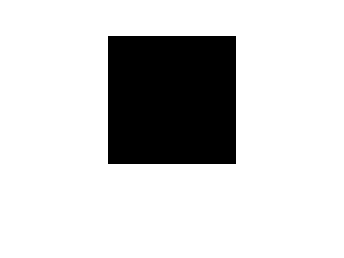


figure
imshow(tiff_stack1)

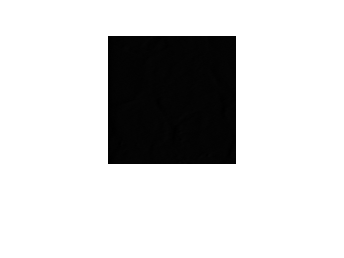


figure
imshow(tiff_stack2)

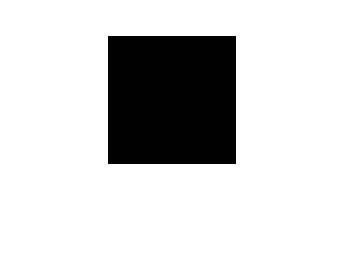


figure
imshow(tiff_stack3)


for i = 594:598
    spc_name = [stateYao.baseName,'FLIM',num2str(i),'.mat']
    load(spc_name)
    eval(['projects_', num2str(i), '=spcSave.projects{1};']);
%     eval(['lifetimeMaps_', num2str(i), '=spc.lifetimeMaps{1};']);
end

spc_name = '20221203AchsensorHEK003FLIM594.mat'

spc_name = '20221203AchsensorHEK003FLIM595.mat'

spc_name = '20221203AchsensorHEK003FLIM596.mat'

spc_name = '20221203AchsensorHEK003FLIM597.mat'

spc_name = '20221203AchsensorHEK003FLIM598.mat'


for i = 594:598
    image_mask_3_top = stateYao.I_ROI_stack_TopPixels{1,1}{1,i-6}{3};
    image_mask_3 = stateYao.images.I_ROI_stack{1,1}{i-6,1}(:,:,3);
    eval(['image_mask_3_', num2str(i), '=image_mask_3;']);
    eval(['image_mask_3_top_', num2str(i), '=image_mask_3_top;']);
end

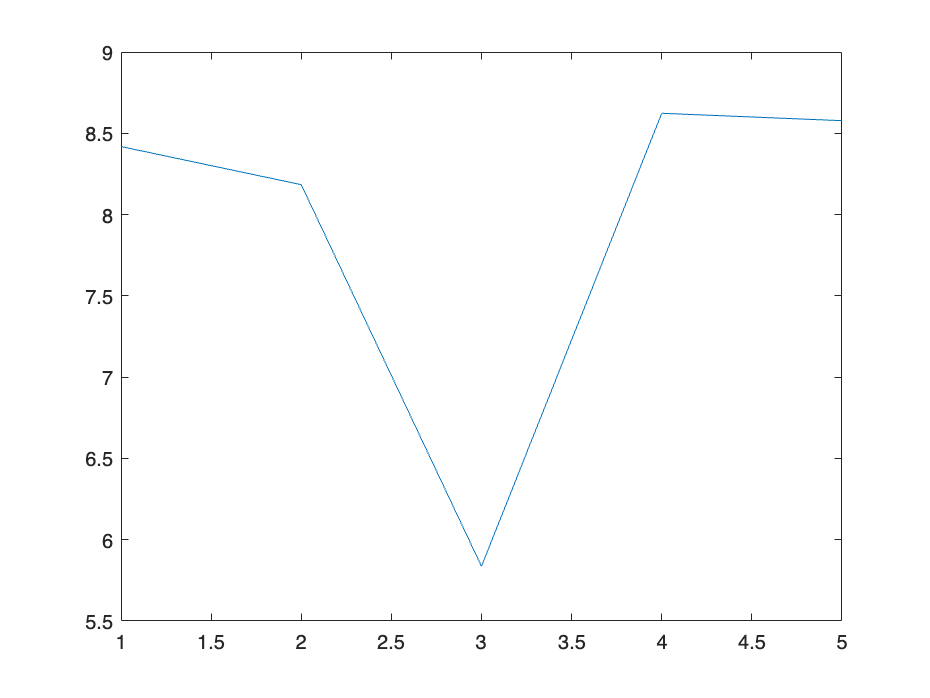

intensity_test = zeros(1,5);
j = 1;

for i = 594:598
    eval(['imageData = imageData_', num2str(i),';'])
    eval(['image_mask = image_mask_3_', num2str(i),';'])
    eval(['image_mask_top = image_mask_3_top_', num2str(i),';'])
%     Yao_calc_Projection(imageData, image_mask)
    intensity_test(j) = Yao_calc_Projection(imageData, image_mask_top);
    j=j+1;
end
figure
plot(intensity_test)

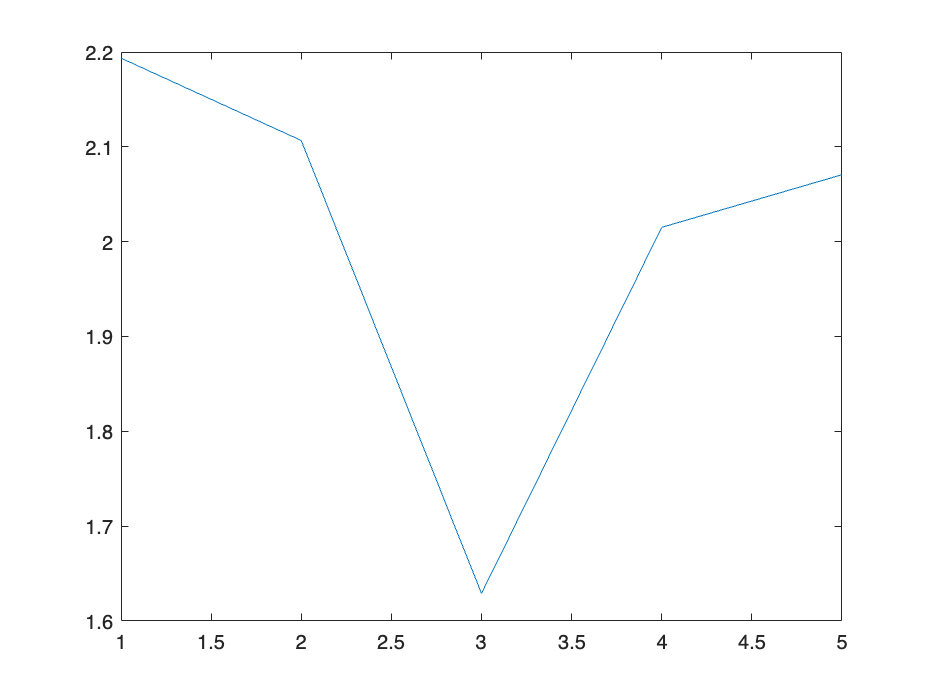

intensity_test = zeros(1,5);
j = 1;
for i = 594:598
    eval(['imageData = imageData_', num2str(i),';'])
    eval(['image_mask = image_mask_3_', num2str(i),';'])
    eval(['image_mask_top = image_mask_3_top_', num2str(i),';'])
    intensity_test(j) = Yao_calc_Projection(imageData, image_mask);
    j=j+1;
%     Yao_calc_Projection(imageData, image_mask_top)
end
 figure
 plot(intensity_test)

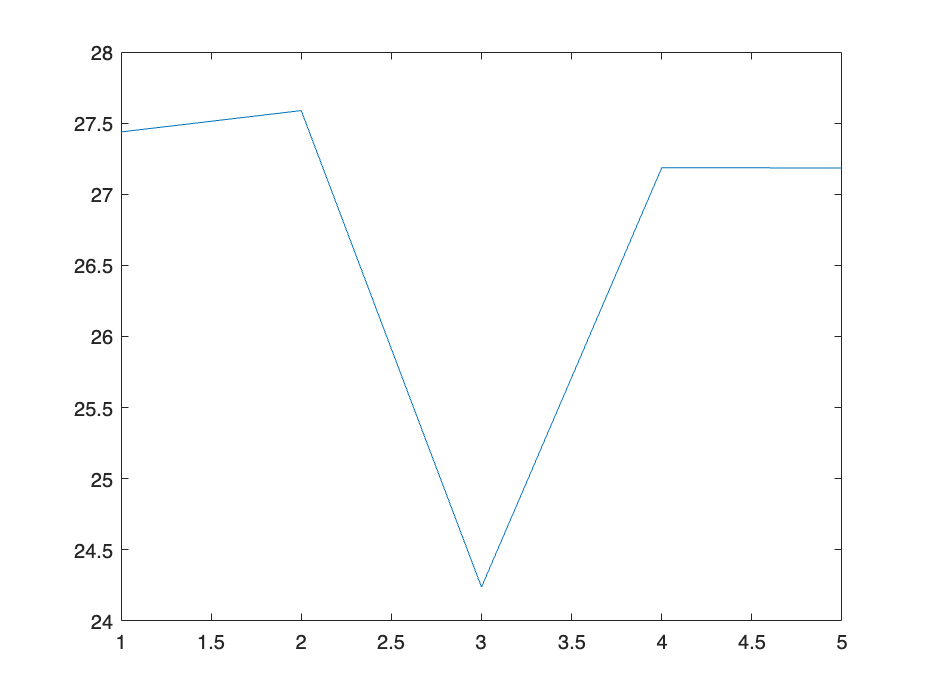

intensity_test = zeros(1,5);
j = 1;
for i = 594:598
    eval(['projects = projects_', num2str(i),';'])
    eval(['image_mask = image_mask_3_', num2str(i),';'])
    eval(['image_mask_top = image_mask_3_top_', num2str(i),';'])
    intensity_test(j) = Yao_calc_Projection(projects, image_mask);
    j=j+1;
%     Yao_calc_Projection(projects, image_mask_top)
end

 figure
 plot(intensity_test)

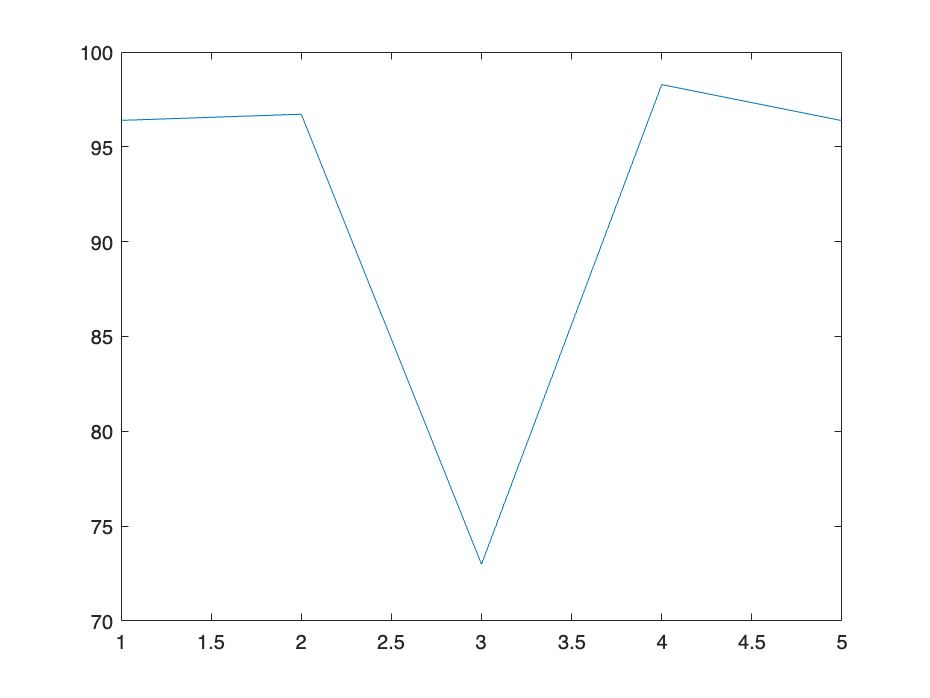

intensity_test = zeros(1,5);
j = 1;
for i = 594:598
    eval(['projects = projects_', num2str(i),';'])
    eval(['image_mask = image_mask_3_', num2str(i),';'])
    eval(['image_mask_top = image_mask_3_top_', num2str(i),';'])
    intensity_test(j) = Yao_calc_Projection(projects, image_mask_top);
    j=j+1;
%     Yao_calc_Projection(projects, image_mask_top)
end

 figure
 plot(intensity_test)

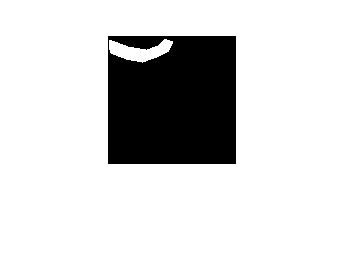

figure
imshow(image_mask_3_596)

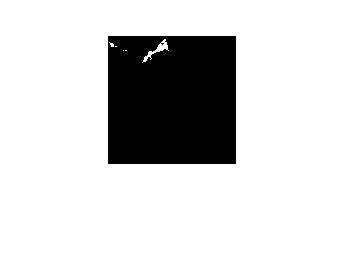

figure
imshow(image_mask_3_top_596)

figure
imshow(image_mask_3_595)

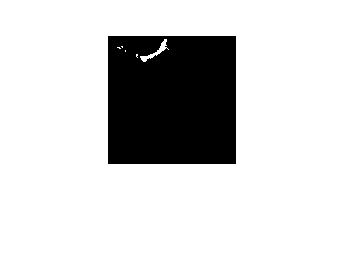

figure
imshow(image_mask_3_top_595)